# ***Robot SCARA 3DDL***

## **1. Modèle géométrique direct pour tourver la matrice de transformation**

### **1.1 Initialisation du Tableau DH :**

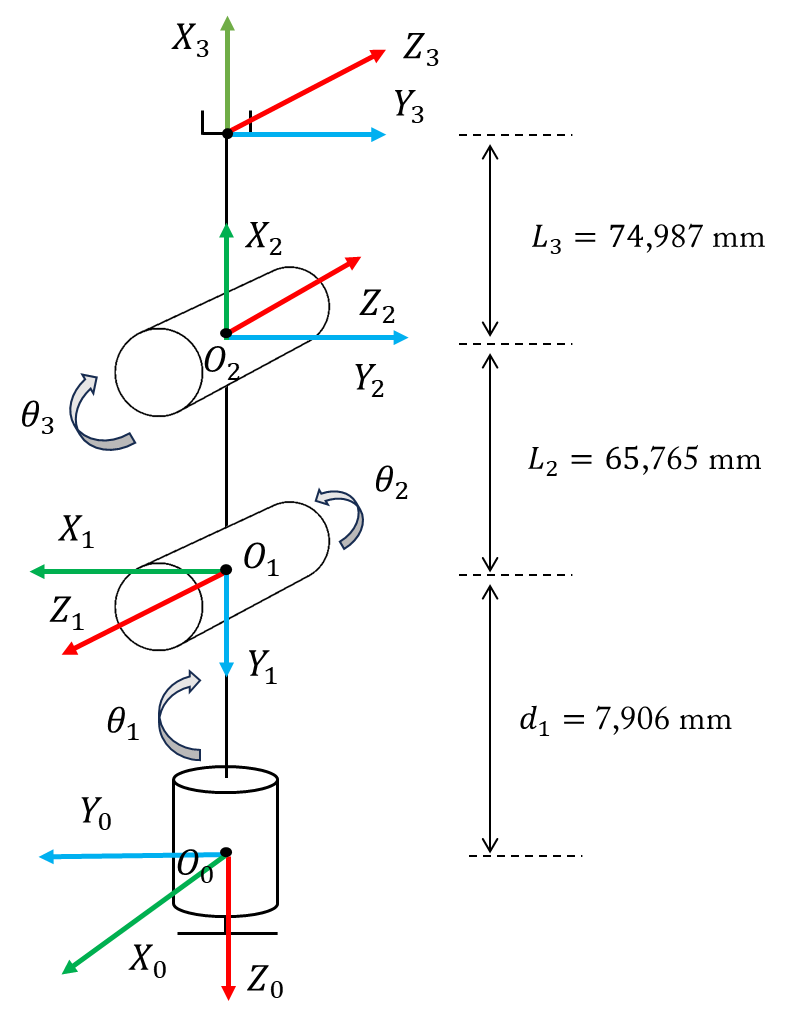

syms  d1 L2 L3 theta1 theta2 theta3 ;

DH_Table = [0 ,    pi/2,   -d1,    theta1-(pi/2) ; 
            L2,    pi  ,     0,    theta2-(pi/2) ; 
            L3,    0   ,     0,    theta3         ]  

$$DH\_Table = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & -d_{1} & \theta_{1}-\frac{\pi }{2}\\ L_{2} & \pi & 0 & \theta_{2}-\frac{\pi }{2}\\ L_{3} & 0 & 0 & \theta_{3} \end{array}\right)$$

### 1.2 Calcule des matrices M01 M12 et M23 :

M01 = matric_homogene(DH_Table(1,:))   

$$M01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}-\frac{\pi }{2}\right) & 0 & \sin\left(\theta_{1}-\frac{\pi }{2}\right) & 0\\ \sin\left(\theta_{1}-\frac{\pi }{2}\right) & 0 & -\cos\left(\theta_{1}-\frac{\pi }{2}\right) & 0\\ 0 & 1 & 0 & -d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M12 = simplify(matric_homogene(DH_Table(2,:))) 

$$M12 = \left(\begin{array}{cccc} \sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & L_{2}\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & -L_{2}\,\cos\left(\theta_{2}\right)\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M23 = simplify(matric_homogene(DH_Table(3,:)))  

$$M23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### 1.3 Calcule de la matrice M02 M03

M02 = simplify(M01 * M12)

$$M02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & L_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \sin\left(\theta_{1}\right) & -L_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & -d_{1}-L_{2}\,\cos\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M03 = simplify(M01 * M12 * M23)  

$$M03 = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(\theta_{2}-\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{2}-\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ -\sin\left(\theta_{2}-\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \cos\left(\theta_{2}-\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\sigma_{1}\\ -\cos\left(\theta_{2}-\theta_{3}\right) & -\sin\left(\theta_{2}-\theta_{3}\right) & 0 & -d_{1}-L_{2}\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{2}-\theta_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{2}\right)+L_{3}\,\sin\left(\theta_{2}-\theta_{3}\right) \end{array}$$

## 2. Modèle Géométrique Inverse : Méthode de Paul

### 2.1 La situation du repère Rn (lié à l'organe terminal)

syms Sx Sy Sz Nx Ny Nz Ax Ay Az Px Py Pz ;

U0 = [ Sx, Nx, Ax, Px ;
       Sy, Ny, Ay, Py ;
       Sz, Nz, Az, Pz ;
       0,  0,  0,  1 ] 

$$U0 = \left(\begin{array}{cccc} \mathrm{Sx} & \mathrm{Nx} & \text{Ax} & \mathrm{Px}\\ \mathrm{Sy} & \mathrm{Ny} & \mathrm{Ay} & \mathrm{Py}\\ \mathrm{Sz} & \mathrm{Nz} & \mathrm{Az} & \mathrm{Pz}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

### 2.2 Première étape : Pré-multiplier par  M01⁻¹ 

M01_inv = simplify(inv(M01))

$$M01\_inv = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & d_{1}\\ -\cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M1 = simplify(M01_inv * U0) ;
eq = M1 == M12*M23 

$$eq = \begin{array}{l} \left(\begin{array}{cccc} \mathrm{Sx}\,\sin\left(\theta_{1}\right)-\mathrm{Sy}\,\cos\left(\theta_{1}\right)=\sigma_{2}-\sigma_{3} & \mathrm{Nx}\,\sin\left(\theta_{1}\right)-\mathrm{Ny}\,\cos\left(\theta_{1}\right)=\sigma_{1} & \text{Ax}\,\sin\left(\theta_{1}\right)-\mathrm{Ay}\,\cos\left(\theta_{1}\right)=0 & \mathrm{Px}\,\sin\left(\theta_{1}\right)-\mathrm{Py}\,\cos\left(\theta_{1}\right)=L_{2}\,\sin\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)+L_{3}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ \mathrm{Sz}=\sigma_{1} & \mathrm{Nz}=\sigma_{3}-\sigma_{2} & \mathrm{Az}=0 & \mathrm{Pz}+d_{1}=-L_{2}\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-L_{3}\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ -\mathrm{Sx}\,\cos\left(\theta_{1}\right)-\mathrm{Sy}\,\sin\left(\theta_{1}\right)=0 & -\mathrm{Nx}\,\cos\left(\theta_{1}\right)-\mathrm{Ny}\,\sin\left(\theta_{1}\right)=0 & -\text{Ax}\,\cos\left(\theta_{1}\right)-\mathrm{Ay}\,\sin\left(\theta_{1}\right)=-1 & -\mathrm{Px}\,\cos\left(\theta_{1}\right)-\mathrm{Py}\,\sin\left(\theta_{1}\right)=0\\ 0=0 & 0=0 & 0=0 & 1=1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{3}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) \end{array}$$

#### 2.2.1 L'ensembles des solutions possible pour Thetha1

equation = -(Px*cos(theta1))-(Py*sin(theta1)) == 0 

$$equation = -\mathrm{Px}\,\cos\left(\theta_{1}\right)-\mathrm{Py}\,\sin\left(\theta_{1}\right)=0$$

Theta1_sol_1 = simplify(solve(equation, theta1, 'Real', true))

$$Theta1\_sol\_1 = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Py}+\sqrt{{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}}}{\mathrm{Px}}\right)\\ 2\,\mathrm{atan}\left(\frac{\mathrm{Py}-\sqrt{{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}}}{\mathrm{Px}}\right) \end{array}\right)$$

### 2.3 Deuxième étape : Pré-multiplier par  M01⁻¹ M12⁻¹ 

M12_inv = simplify(inv(M12));
M1 = simplify(M01_inv * M12_inv * U0) ;
eq = M1 == M23 

$$eq = \left(\begin{array}{cccc} \mathrm{Sx}\,\cos\left(\theta_{1}-\theta_{2}\right)-\mathrm{Sy}\,\sin\left(\theta_{1}-\theta_{2}\right)=\cos\left(\theta_{3}\right) & \mathrm{Nx}\,\cos\left(\theta_{1}-\theta_{2}\right)-\mathrm{Ny}\,\sin\left(\theta_{1}-\theta_{2}\right)=-\sin\left(\theta_{3}\right) & \text{Ax}\,\cos\left(\theta_{1}-\theta_{2}\right)-\mathrm{Ay}\,\sin\left(\theta_{1}-\theta_{2}\right)=0 & \mathrm{Px}\,\cos\left(\theta_{1}-\theta_{2}\right)-L_{2}\,\sin\left(\theta_{1}\right)-\mathrm{Py}\,\sin\left(\theta_{1}-\theta_{2}\right)=L_{3}\,\cos\left(\theta_{3}\right)\\ -\mathrm{Sz}=\sin\left(\theta_{3}\right) & -\mathrm{Nz}=\cos\left(\theta_{3}\right) & -\mathrm{Az}=0 & d_{1}-\mathrm{Pz}=L_{3}\,\sin\left(\theta_{3}\right)\\ \mathrm{Sy}\,\cos\left(\theta_{1}-\theta_{2}\right)+\mathrm{Sx}\,\sin\left(\theta_{1}-\theta_{2}\right)=0 & \mathrm{Ny}\,\cos\left(\theta_{1}-\theta_{2}\right)+\mathrm{Nx}\,\sin\left(\theta_{1}-\theta_{2}\right)=0 & \mathrm{Ay}\,\cos\left(\theta_{1}-\theta_{2}\right)+\text{Ax}\,\sin\left(\theta_{1}-\theta_{2}\right)=1 & L_{2}\,\cos\left(\theta_{1}\right)+\mathrm{Py}\,\cos\left(\theta_{1}-\theta_{2}\right)+\mathrm{Px}\,\sin\left(\theta_{1}-\theta_{2}\right)=0\\ 0=0 & 0=0 & 0=0 & 1=1 \end{array}\right)$$

#### 2.3.1 L'ensembles des solutions possible pour Thetha3

equation = d1 - Pz == L3*sin(theta3)  

$$equation = d_{1}-\mathrm{Pz}=L_{3}\,\sin\left(\theta_{3}\right)$$

Theta3_sol1 = simplify(solve(equation , theta3)) 

$$Theta3\_sol1 = \left(\begin{array}{c} -\mathrm{asin}\left(\frac{\mathrm{Pz}-d_{1}}{L_{3}}\right)\\ \pi +\mathrm{asin}\left(\frac{\mathrm{Pz}-d_{1}}{L_{3}}\right) \end{array}\right)$$

#### 2.3.2 L'ensembles des solutions possible pour Thetha2

equation = Px*cos(theta1 - theta2) - L2*sin(theta1) - Py*sin(theta1 - theta2) == L3*cos(theta3) 

$$equation = \mathrm{Px}\,\cos\left(\theta_{1}-\theta_{2}\right)-L_{2}\,\sin\left(\theta_{1}\right)-\mathrm{Py}\,\sin\left(\theta_{1}-\theta_{2}\right)=L_{3}\,\cos\left(\theta_{3}\right)$$

Theta2_sol1 = simplify(solve(equation , theta2, 'Real',true))

$$Theta2\_sol1 = \begin{array}{l} \left(\begin{array}{c} \theta_{1}+2\,\mathrm{atan}\left(\frac{\mathrm{Py}+\sigma_{1}}{\mathrm{Px}+L_{3}\,\cos\left(\theta_{3}\right)+L_{2}\,\sin\left(\theta_{1}\right)}\right)\\ \theta_{1}+2\,\mathrm{atan}\left(\frac{\mathrm{Py}-\sigma_{1}}{\mathrm{Px}+L_{3}\,\cos\left(\theta_{3}\right)+L_{2}\,\sin\left(\theta_{1}\right)}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{-{L_{2}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}-2\,L_{2}\,L_{3}\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-{L_{3}}^{2}\,{\cos\left(\theta_{3}\right)}^{2}+{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}} \end{array}$$

## 3. Modèle Géométrique Inverse : Méthode Géométrique

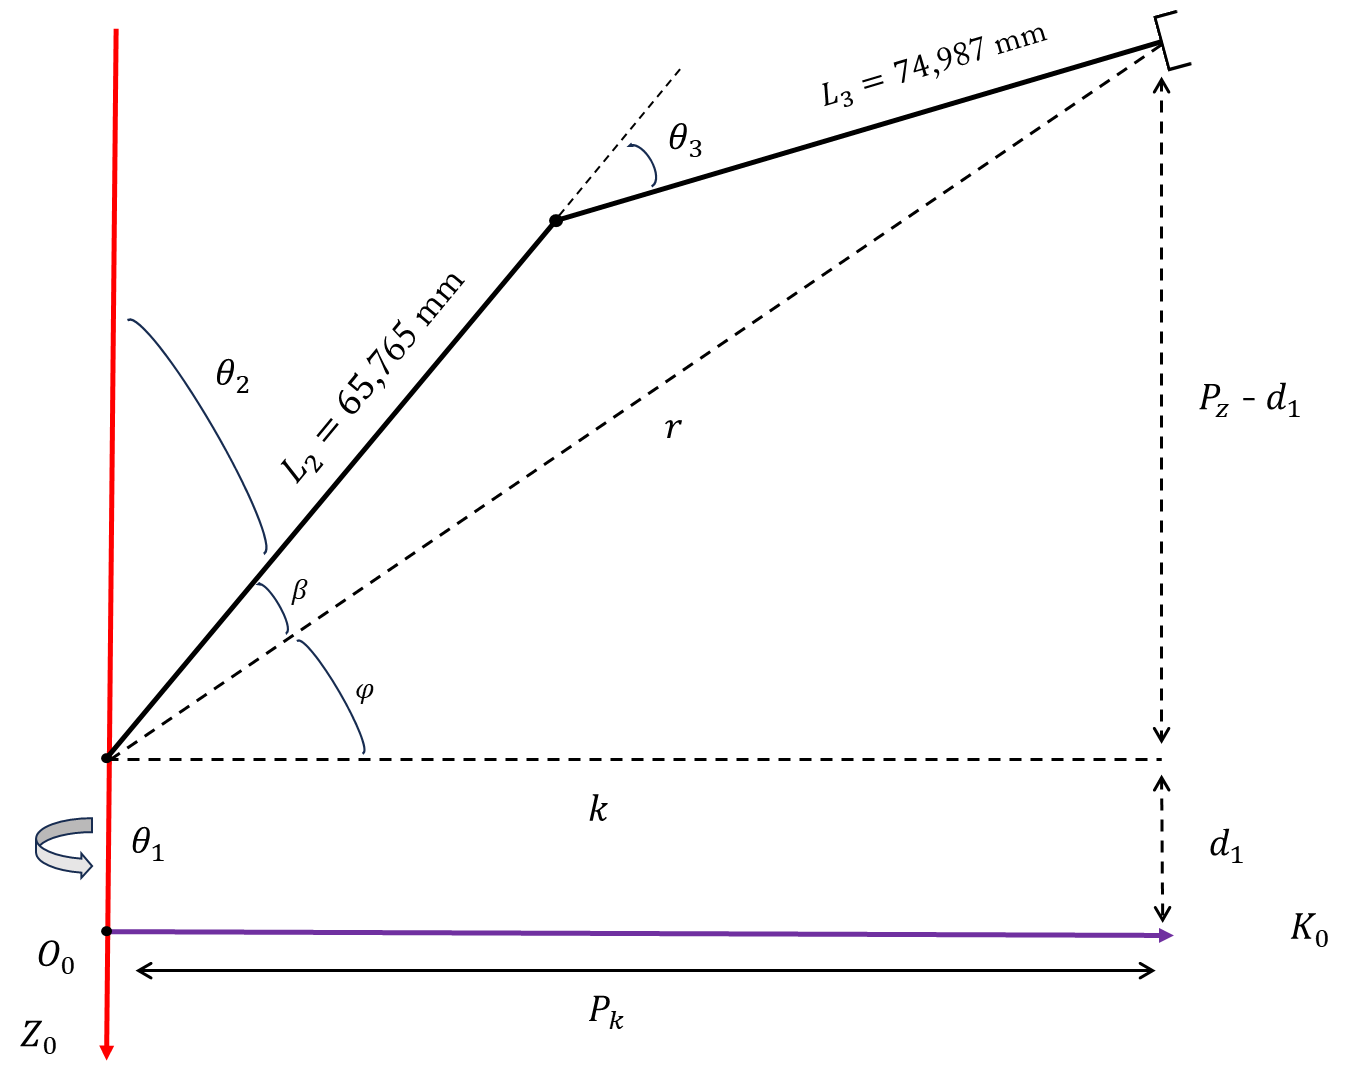

syms r k beta alpha Pk theta1_geo theta2_geo theta3_geo Px Py Pz L2 L3 d1;
Pk = sqrt(Px^2 + Py^2) 

$$Pk = \sqrt{{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}}$$

r  = sqrt(Pk^2 + (Pz - d1)^2)

$$r = \sqrt{{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}+{\left(\mathrm{Pz}-d_{1}\right)}^{2}}$$

### 3.1 La solution possible pour Thetha1

theta1_sol_geo = atan2(Py, Px)

$$theta1\_sol\_geo = \text{atan2}\left(\mathrm{Py},\mathrm{Px}\right)$$

### 3.2 La solution possible pour Thetha2

sin(alpha) = (Pz - d1) / r ; 
alpha = asin(sin(alpha))

$$alpha = \mathrm{asin}\left(\frac{\mathrm{Pz}-d_{1}}{\sqrt{{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}+{\left(\mathrm{Pz}-d_{1}\right)}^{2}}}\right)$$

cos(beta) = (L2^2 + r^2 - L3^2) / (2 * L2 * r ) ;
beta = acos(cos(beta))

$$beta = \mathrm{acos}\left(\frac{{L_{2}}^{2}-{L_{3}}^{2}+{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}+{\left(\mathrm{Pz}-d_{1}\right)}^{2}}{2\,L_{2}\,\sqrt{{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}+{\left(\mathrm{Pz}-d_{1}\right)}^{2}}}\right)$$

theta2_sol_geo = (pi/2)-(alpha + beta)

$$theta2\_sol\_geo = \frac{\pi }{2}-\mathrm{asin}\left(\frac{\mathrm{Pz}-d_{1}}{\sqrt{{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}+{\left(\mathrm{Pz}-d_{1}\right)}^{2}}}\right)-\mathrm{acos}\left(\frac{{L_{2}}^{2}-{L_{3}}^{2}+{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}+{\left(\mathrm{Pz}-d_{1}\right)}^{2}}{2\,L_{2}\,\sqrt{{\mathrm{Px}}^{2}+{\mathrm{Py}}^{2}+{\left(\mathrm{Pz}-d_{1}\right)}^{2}}}\right)$$

### 3.3 La solution possible pour Thetha3

cos(theta3_geo) = -(L2^2 + L3^2 - r^2) / (2 * L2 * L3 ) ;
theta3_sol_geo = acos(cos(theta3_geo))

$$theta3\_sol\_geo = \mathrm{acos}\left(\frac{{\mathrm{Px}}^{2}-{L_{3}}^{2}-{L_{2}}^{2}+{\mathrm{Py}}^{2}+{\left(\mathrm{Pz}-d_{1}\right)}^{2}}{2\,L_{2}\,L_{3}}\right)$$

## 4. Trajectoire Calculée (Les Thetas en fonctions du temps) 

### 4.1 Définition de la trajectoire articulaire (Polynôme d'ordre 5)

syms t T_total
syms theta1_start theta1_end theta2_start theta2_end theta3_start theta3_end 

#### 4.1.1 Paramètre de progression s(t) qui va de 0 à 1

s = 10*(t/T_total)^3 - 15*(t/T_total)^4 + 6*(t/T_total)^5

$$s = \frac{10\,t^{3}}{{T_{\mathrm{total}}}^{3}}-\frac{15\,t^{4}}{{T_{\mathrm{total}}}^{4}}+\frac{6\,t^{5}}{{T_{\mathrm{total}}}^{5}}$$

#### 4.1.2 Évolution de chaque angle en fonction du temps

theta1_t = theta1_start + s*(theta1_end - theta1_start) 

$$theta1\_t = \theta_{1,\mathrm{start}}+\left(\theta_{1,\mathrm{end}}-\theta_{1,\mathrm{start}}\right)\,\left(\frac{10\,t^{3}}{{T_{\mathrm{total}}}^{3}}-\frac{15\,t^{4}}{{T_{\mathrm{total}}}^{4}}+\frac{6\,t^{5}}{{T_{\mathrm{total}}}^{5}}\right)$$

theta2_t = theta2_start + s*(theta2_end - theta2_start)

$$theta2\_t = \theta_{2,\mathrm{start}}+\left(\theta_{2,\mathrm{end}}-\theta_{2,\mathrm{start}}\right)\,\left(\frac{10\,t^{3}}{{T_{\mathrm{total}}}^{3}}-\frac{15\,t^{4}}{{T_{\mathrm{total}}}^{4}}+\frac{6\,t^{5}}{{T_{\mathrm{total}}}^{5}}\right)$$

theta3_t = theta3_start + s*(theta3_end - theta3_start)

$$theta3\_t = \theta_{3,\mathrm{start}}+\left(\theta_{3,\mathrm{end}}-\theta_{3,\mathrm{start}}\right)\,\left(\frac{10\,t^{3}}{{T_{\mathrm{total}}}^{3}}-\frac{15\,t^{4}}{{T_{\mathrm{total}}}^{4}}+\frac{6\,t^{5}}{{T_{\mathrm{total}}}^{5}}\right)$$

## 5. Modéle Dynamique

clc 
clear all
syms  d1 L2 L3 theta1 theta2 theta3 ;

DH_Table = [0 ,    pi/2,   -d1,    theta1-(pi/2) ; 
            L2,    pi  ,     0,    theta2-(pi/2) ; 
            L3,    0   ,     0,    theta3         ]  

$$DH\_Table = \left(\begin{array}{cccc} 0 & \frac{\pi }{2} & -d_{1} & \theta_{1}-\frac{\pi }{2}\\ L_{2} & \pi & 0 & \theta_{2}-\frac{\pi }{2}\\ L_{3} & 0 & 0 & \theta_{3} \end{array}\right)$$

M01 = simplify(matric_homogene(DH_Table(1,:))) 

$$M01 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & -d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M12 = simplify(matric_homogene(DH_Table(2,:)))  

$$M12 = \left(\begin{array}{cccc} \sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right) & 0 & L_{2}\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & -L_{2}\,\cos\left(\theta_{2}\right)\\ 0 & 0 & -1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M23 = simplify(matric_homogene(DH_Table(3,:)))  

$$M23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{3}\,\cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & L_{3}\,\sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M02 = simplify(M01 * M12)

$$M02 = \left(\begin{array}{cccc} \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & L_{2}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \sin\left(\theta_{1}\right) & -L_{2}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & -d_{1}-L_{2}\,\cos\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

M03 = simplify(M01 * M12 * M23)

$$M03 = \begin{array}{l} \left(\begin{array}{cccc} \sin\left(\theta_{2}-\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{2}-\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ -\sin\left(\theta_{2}-\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \cos\left(\theta_{2}-\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right)\,\sigma_{1}\\ -\cos\left(\theta_{2}-\theta_{3}\right) & -\sin\left(\theta_{2}-\theta_{3}\right) & 0 & -d_{1}-L_{2}\,\cos\left(\theta_{2}\right)-L_{3}\,\cos\left(\theta_{2}-\theta_{3}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\sin\left(\theta_{2}\right)+L_{3}\,\sin\left(\theta_{2}-\theta_{3}\right) \end{array}$$

### 5.1 L'energie cinétique partie translation

#### 5.1.1 Les Centres de gravités

syms OG1 OG2 OG3 O0O1 O1O2 O2O3 theta_dot theta1_dot theta2_dot theta3_dot Jv01 Jv02 Jv03 K_translation m1 m2 m3 Jw1 Jw2 Jw3 R01 R02 R03
theta_dot = [theta1_dot; theta2_dot ; theta3_dot ] ;
O0O1 = M01(1:3, 4) 

$$O0O1 = \left(\begin{array}{c} 0\\ 0\\ -d_{1} \end{array}\right)$$

O1O2 = M12(1:3, 4) 

$$O1O2 = \left(\begin{array}{c} L_{2}\,\sin\left(\theta_{2}\right)\\ -L_{2}\,\cos\left(\theta_{2}\right)\\ 0 \end{array}\right)$$

O2O3 = M23(1:3, 4) 

$$O2O3 = \left(\begin{array}{c} L_{3}\,\cos\left(\theta_{3}\right)\\ L_{3}\,\sin\left(\theta_{3}\right)\\ 0 \end{array}\right)$$

OG1 = O0O1 / 2 

$$OG1 = \left(\begin{array}{c} 0\\ 0\\ -\frac{d_{1}}{2} \end{array}\right)$$

OG2 = O0O1 + (O1O2 / 2)

$$OG2 = \left(\begin{array}{c} \frac{L_{2}\,\sin\left(\theta_{2}\right)}{2}\\ -\frac{L_{2}\,\cos\left(\theta_{2}\right)}{2}\\ -d_{1} \end{array}\right)$$

OG3 = O0O1 + O1O2 + (O2O3 / 2)

$$OG3 = \left(\begin{array}{c} \frac{L_{3}\,\cos\left(\theta_{3}\right)}{2}+L_{2}\,\sin\left(\theta_{2}\right)\\ \frac{L_{3}\,\sin\left(\theta_{3}\right)}{2}-L_{2}\,\cos\left(\theta_{2}\right)\\ -d_{1} \end{array}\right)$$

#### 5.1.2 Calcule des Jacobiens pour les Vitesses linéaire

V01 = diff(OG1, theta1) * theta1_dot 

$$V01 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

V02 = diff(OG2 , theta2) * theta2_dot 

$$V02 = \left(\begin{array}{c} \frac{L_{2}\,\theta_{\dot{2}}\,\cos\left(\theta_{2}\right)}{2}\\ \frac{L_{2}\,\theta_{\dot{2}}\,\sin\left(\theta_{2}\right)}{2}\\ 0 \end{array}\right)$$

V03 = [  (-L3*theta3_dot*sin(theta3))/2 + L2*theta2_dot*cos(theta2)     ; (L3*theta3_dot*cos(theta3))/2 + L2*theta2_dot*sin(theta2)      ; 0 ]         

$$V03 = \left(\begin{array}{c} L_{2}\,\theta_{\dot{2}}\,\cos\left(\theta_{2}\right)-\frac{L_{3}\,\theta_{\dot{3}}\,\sin\left(\theta_{3}\right)}{2}\\ L_{2}\,\theta_{\dot{2}}\,\sin\left(\theta_{2}\right)+\frac{L_{3}\,\theta_{\dot{3}}\,\cos\left(\theta_{3}\right)}{2}\\ 0 \end{array}\right)$$

Jv01 = [0, 0, 0 ;
        0, 0, 0 ;
        0, 0, 0 ]

Jv01 =      0     0     0
     0     0     0
     0     0     0


Jv02 = [ 0 ,  (L2*cos(theta2))/2 ,   0 ;
         0 ,  (L2*sin(theta2))/2 ,   0 ; 
         0 ,   0                 ,   0  ]

$$Jv02 = \left(\begin{array}{ccc} 0 & \frac{L_{2}\,\cos\left(\theta_{2}\right)}{2} & 0\\ 0 & \frac{L_{2}\,\sin\left(\theta_{2}\right)}{2} & 0\\ 0 & 0 & 0 \end{array}\right)$$

Jv03 = [ 0 ,   L2*cos(theta2)  ,  -(L3*sin(theta3))/2 ; 
         0 ,   L2*cos(theta2)  ,   (L3*cos(theta3))/2 ; 
         0 ,   0               ,    0                  ]

$$Jv03 = \left(\begin{array}{ccc} 0 & L_{2}\,\cos\left(\theta_{2}\right) & -\frac{L_{3}\,\sin\left(\theta_{3}\right)}{2}\\ 0 & L_{2}\,\cos\left(\theta_{2}\right) & \frac{L_{3}\,\cos\left(\theta_{3}\right)}{2}\\ 0 & 0 & 0 \end{array}\right)$$

#### 5.1.2 Calcule L'energie cinétique partie translation 

K_translation = simplify((m1 * transpose(Jv01) * Jv01) + (m2 * transpose(Jv02) * Jv02)+ (m3 * transpose(Jv03) * Jv03))

$$K\_translation = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & \frac{{L_{2}}^{2}\,\left(-8\,m_{3}\,{\sin\left(\theta_{2}\right)}^{2}+m_{2}+8\,m_{3}\right)}{4} & \frac{\sqrt{2}\,L_{2}\,L_{3}\,m_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}+\frac{\pi }{4}\right)}{2}\\ 0 & \frac{\sqrt{2}\,L_{2}\,L_{3}\,m_{3}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}+\frac{\pi }{4}\right)}{2} & \frac{{L_{3}}^{2}\,m_{3}}{4} \end{array}\right)$$

### 5.2 L'energie cinétique partie rotation

#### 5.2.1 Calcule des Jacobiens pour les Vitesses angulaire

Jw1 = [ 0 , 0 , 0 ;
        0 , 0 , 0 ;
        1 , 0 , 0 ]

Jw1 =      0     0     0
     0     0     0
     1     0     0


Jw2 = [ 0 , -cos(theta1) , 0 ;
        0 , -sin(theta1) , 0 ;
        1 ,  0           , 0 ]

$$Jw2 = \left(\begin{array}{ccc} 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & -\sin\left(\theta_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

Jw3 = [ 0 , -cos(theta1) , cos(theta1) ;
        0 , -sin(theta1) , sin(theta1) ;
        1 , 0           , 0           ]

$$Jw3 = \left(\begin{array}{ccc} 0 & -\cos\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\\ 0 & -\sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ 1 & 0 & 0 \end{array}\right)$$

#### 5.2.2 Calcule des matrices de rotation 

R01 = simplify(M01(1:3, 1:3))

$$R01 = \left(\begin{array}{ccc} \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right) & 0 & -\sin\left(\theta_{1}\right)\\ 0 & 1 & 0 \end{array}\right)$$

R02 = simplify(M02(1:3, 1:3))

$$R02 = \left(\begin{array}{ccc} \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\\ -\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right) & \sin\left(\theta_{1}\right)\\ -\cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 \end{array}\right)$$

R03 = simplify(M03(1:3, 1:3))

$$R03 = \left(\begin{array}{ccc} \sin\left(\theta_{2}-\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{2}-\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\\ -\sin\left(\theta_{2}-\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \cos\left(\theta_{2}-\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\\ -\cos\left(\theta_{2}-\theta_{3}\right) & -\sin\left(\theta_{2}-\theta_{3}\right) & 0 \end{array}\right)$$

#### 5.2.3 Tenseur d’inertie 

syms Ixx1 Iyy1 Izz1 real % Inerties du corps 1
syms Ixx2 Iyy2 Izz2 real % Inerties du corps 2
syms Ixx3 Iyy3 Izz3 real % Inerties du corps 2
syms I1 I2 I3 I4 K_rotation K_total 

%% Masses (Unités : kg)
m_P1 = 0.006509;
m_P2 = 0.008157;
m_P3 = 0.010337;
m_P4 = 0.009495;
m_End = 0.000363;


% --- I1 : Tenseurs pour P1 et P2 ---
I_P1 = [0.6571, 0, 0; 0, 0.6571, 0; 0, 0, 1.2821] * 1e-6;
I_P2 = [0.8421, 0, 0; 0, 0.8583, 0; 0, 0, 1.3654] * 1e-6;
m1 = m_P1 + m_P2

m1 = 0.0147

I1 = I_P1 + I_P2 

I1 = 1.0e-05 *

    0.1499         0         0
         0    0.1515         0
         0         0    0.2647


% --- I2 : Tenseur pour P3 ---
% Ici, les PoI sont inclus car non nuls dans le fichier
m2 = m_P2 

m2 = 0.0082

I2 = [3.2476, -7.994e-6, -2.058e-6; ...
     -7.994e-6, 3.2578, -1.025e-6; ...
     -2.058e-6, -1.025e-6, 0.2857] * 1e-6

I2 = 1.0e-05 *

    0.3248   -0.0000   -0.0000
   -0.0000    0.3258   -0.0000
   -0.0000   -0.0000    0.0286


% --- I3 : Tenseurs pour P4 et End ---
m3 = m_P4 + m_End

m3 = 0.0099

I3 = ([2.4384, 0, 0; 0, 2.4351, 0; 0, 0, 0.2588] * 1e-6) + ([0.0055, 0, 0; 0, 0.0055, 0; 0, 0, 0.0101] * 1e-6) 

I3 = 1.0e-05 *

    0.2444         0         0
         0    0.2441         0
         0         0    0.0269


#### 5.1.2 Calcule L'energie cinétique partie rotation

K_rotation = simplify((transpose(Jw1) * R01 * I1 * transpose(R01) * Jw1) + (transpose(Jw2) * R02 * I2 * transpose(R02) * Jw2) + ...
                      (transpose(Jw3) * R03 * I3 * transpose(R03) * Jw3))

$$K\_rotation = \begin{array}{l} \left(\begin{array}{ccc} \frac{7791904696735\,\cos\left(2\,\theta_{2}\right)\,\cos\left(2\,\theta_{3}\right)}{4722366482869645213696}-\frac{4948046337023665\,\sin\left(2\,\theta_{2}\right)}{618970019642690137449562112}-\frac{6021017265659\,\cos\left(2\,\theta_{2}\right)}{1180591620717411303424}+\frac{7791904696735\,\sin\left(2\,\theta_{2}\right)\,\sin\left(2\,\theta_{3}\right)}{4722366482869645213696}+\frac{34049915169759145}{4722366482869645213696} & \sigma_{1} & 0\\ \sigma_{1} & \frac{2619024451399505}{4722366482869645213696} & -\frac{2539688694487295}{9444732965739290427392}\\ 0 & -\frac{2539688694487295}{9444732965739290427392} & \frac{2539688694487295}{9444732965739290427392} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{5095361201698625\,\cos\left(\theta_{2}\right)}{2475880078570760549798248448}-\frac{5075554161070059\,\sin\left(\theta_{2}\right)}{4951760157141521099596496896} \end{array}$$

### 5.3 L'energie cinétique Total 

K_total = simplify ( (1/2) * transpose(theta_dot) * (K_translation + K_rotation) * theta_dot )

$$K\_total = \frac{34049915169759145\,{\theta_{\dot{1}}}^{2}}{9444732965739290427392}-\frac{6021017265659\,{\theta_{\dot{1}}}^{2}\,\cos\left(2\,\theta_{2}\right)}{2361183241434822606848}-\frac{4948046337023665\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{2}\right)}{1237940039285380274899124224}-\frac{2539688694487295\,\theta_{\dot{2}}\,\theta_{\dot{3}}}{9444732965739290427392}+\frac{2619024451399505\,{\theta_{\dot{2}}}^{2}}{9444732965739290427392}+\frac{2539688694487295\,{\theta_{\dot{3}}}^{2}}{18889465931478580854784}-\frac{5095361201698625\,\theta_{\dot{1}}\,\theta_{\dot{2}}\,\cos\left(\theta_{2}\right)}{2475880078570760549798248448}-\frac{5075554161070059\,\theta_{\dot{1}}\,\theta_{\dot{2}}\,\sin\left(\theta_{2}\right)}{4951760157141521099596496896}+\frac{{L_{2}}^{2}\,m_{2}\,{\theta_{\dot{2}}}^{2}}{8}+{L_{2}}^{2}\,m_{3}\,{\theta_{\dot{2}}}^{2}+\frac{{L_{3}}^{2}\,m_{3}\,{\theta_{\dot{3}}}^{2}}{8}+\frac{7791904696735\,{\theta_{\dot{1}}}^{2}\,\cos\left(2\,\theta_{2}\right)\,\cos\left(2\,\theta_{3}\right)}{9444732965739290427392}+\frac{7791904696735\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{2}\right)\,\sin\left(2\,\theta_{3}\right)}{9444732965739290427392}-{L_{2}}^{2}\,m_{3}\,{\theta_{\dot{2}}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}+\frac{\sqrt{2}\,L_{2}\,L_{3}\,m_{3}\,\theta_{\dot{2}}\,\theta_{\dot{3}}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}+\frac{\pi }{4}\right)}{2}$$

### 5.4 L'energie Potentiel Total

syms V g L
V = simplify([0 , 0 , g] * ( (OG1 * m1) + (OG2 * m2) + (OG3 * m3) ) )

$$V = -\frac{7306063574693589\,d_{1}\,g}{288230376151711744}$$

### 5.5 Le Lagrangien L

L = simplify (K_total - V) 

$$L = \frac{7306063574693589\,d_{1}\,g}{288230376151711744}-\frac{2539688694487295\,\theta_{\dot{2}}\,\theta_{\dot{3}}}{9444732965739290427392}-\frac{6021017265659\,{\theta_{\dot{1}}}^{2}\,\cos\left(2\,\theta_{2}\right)}{2361183241434822606848}-\frac{4948046337023665\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{2}\right)}{1237940039285380274899124224}+\frac{34049915169759145\,{\theta_{\dot{1}}}^{2}}{9444732965739290427392}+\frac{2619024451399505\,{\theta_{\dot{2}}}^{2}}{9444732965739290427392}+\frac{2539688694487295\,{\theta_{\dot{3}}}^{2}}{18889465931478580854784}-\frac{5095361201698625\,\theta_{\dot{1}}\,\theta_{\dot{2}}\,\cos\left(\theta_{2}\right)}{2475880078570760549798248448}-\frac{5075554161070059\,\theta_{\dot{1}}\,\theta_{\dot{2}}\,\sin\left(\theta_{2}\right)}{4951760157141521099596496896}+\frac{{L_{2}}^{2}\,m_{2}\,{\theta_{\dot{2}}}^{2}}{8}+{L_{2}}^{2}\,m_{3}\,{\theta_{\dot{2}}}^{2}+\frac{{L_{3}}^{2}\,m_{3}\,{\theta_{\dot{3}}}^{2}}{8}+\frac{7791904696735\,{\theta_{\dot{1}}}^{2}\,\cos\left(2\,\theta_{2}\right)\,\cos\left(2\,\theta_{3}\right)}{9444732965739290427392}+\frac{7791904696735\,{\theta_{\dot{1}}}^{2}\,\sin\left(2\,\theta_{2}\right)\,\sin\left(2\,\theta_{3}\right)}{9444732965739290427392}-{L_{2}}^{2}\,m_{3}\,{\theta_{\dot{2}}}^{2}\,{\sin\left(\theta_{2}\right)}^{2}+\frac{\sqrt{2}\,L_{2}\,L_{3}\,m_{3}\,\theta_{\dot{2}}\,\theta_{\dot{3}}\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}+\frac{\pi }{4}\right)}{2}$$